runNumber = 15;

files = dir(fullfile(pwd, 'PID_Run*.csv'));
names = {files.name};
idx = find(startsWith(names, sprintf('PID_Run%02d_', runNumber)), 1);
data = readtable(fullfile(pwd, names{idx}));
tok = regexp(names{idx}, 'Kp(\d+(?:\.\d+)?)_Ki(\d+(?:\.\d+)?)_Kd(\d+(?:\.\d+)?)', 'tokens', 'once');

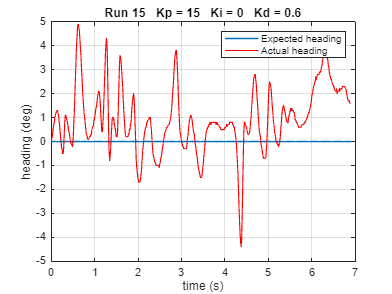

figure
plot(data.time_s, data.desired_heading_deg, 'LineWidth', 1.5)
hold on
plot(data.time_s, data.actual_heading_deg, 'r', 'LineWidth', 1)
hold off
grid on
xlabel('time (s)')
ylabel('heading (deg)')
%legend('Expected heading', 'Actual heading', 'Location', 'southeast')
legend('Expected heading', 'Actual heading', 'Location', 'northeast')
title(sprintf('Run %d   Kp = %s   Ki = %s   Kd = %s', runNumber, tok{1}, tok{2}, tok{3}))